# More Tricks with MATLAB

## Background

This is a [Mathcad Live Script](https://www.mathworks.com/products/matlab/live-editor.html), similar to [R Studio's "Notebook"](https://rmarkdown.rstudio.com/r_notebooks.html) and the [Jupyter Notebooks](http://jupyter.org) which allow us to publish "code" in a manner that is sharable and can intermix elements of a traditional document, programming code and its results.

Here we will show how we can do many of the tricks we've done in Excel and Mathcad in ohter sections in the class.

Note that we are also ommitting the semi-colon here to increase the "verbosity" (screen output) for this exercise.  This is mostly to hopefully enhance the walk-through of this activity.

Let's start with Statistics

## Part 1: Stat-Fu!  

Let's take a case with with our age-height problem.


$$age=\left\lbrack \begin{array}{c}
0\\
5\\
8\\
12\\
16\\
18
\end{array}\right\rbrack$$
     
$$height=\left\lbrack \begin{array}{c}
20\ldotp 0\\
36\ldotp 2\\
52\ldotp 0\\
60\ldotp 0\\
69\ldotp 2\\
70\ldotp 0
\end{array}\right\rbrack$$


Let's create a input these values into a pair of array....

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Initial Values
%
%  here are creating two vertical arrays (note the use of the 
%   semicolons between elements.  Thus, these are 1c x 6r
%

age    = [  0.0;  5.0;  8.0; 12.0; 16.0; 18.0 ];
height = [ 20.0; 36.2; 52.0; 60.0; 69.2; 70.0 ];

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Let's do some basic stats...

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Some basic stats (dropping the semocolons so we can see the
%   results as we calculate them...
%

mean_age    = mean(age)

mean_age = 9.8333


mean_height = mean(height)

mean_height = 51.2333


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Now let's implement a linear regression...

If you've had stats with R this hopefully will look familiar.  Indeed, I wouldn't want to be a intellectual property lawyer.  (I mean, interoperatbility between languages is one thing but....)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  For you R veterans (and soon you ALL will be R veterans) 
%    you will find yourself at home here.  We first group 
%    our data together into a structure called a table.

data_table = table(age, height)

data_table = 6×2 table
    age    height
    ___    ______

     0        20 
     5      36.2 
     8        52 
    12        60 
    16      69.2 
    18        70 



% And we can create a regression model or equation

% First we'll set things up for a linear equation...

regression_model_a_h  = 'height ~ age';         

% Then we'll set things up for a quadradic solution

regressioh_model_a2_h = 'height ~ age + age^2'  

regressioh_model_a2_h = 'height ~ age + age^2'


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

And yes, R-skateers, this is R-Fu.  R has become a working standard in statistics software and you'd be a fool not to borrow it when you can legally get a way with it ;-)   I believe there is another [Tom Lehrer song](https://www.youtube.com/watch?v=gXlfXirQF3A) in there somewhere.

Specifically the lead function here is the [fitlim()](https://www.mathworks.com/help/stats/fitlm.html?s_tid=srchtitle) function...

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  The fitlm function (JFGI!) is right out of R and does a a 
%     "linear" model based on what we have below.  Notice though 
%     that it does multivariate fun too!

lm_a  = fitlm(data_table, regression_model_a_h);
lm_a2 = fitlm(data_table, regressioh_model_a2_h);

% some of these fields should be familiar.  For example
%  you can see the correlation coefficient, root mean
%  square error and some others like the St (SST), Sr (SSE)
%  and others.. -- SSR here is your sum{[y(x)-mean(y)]^2} which 
%  we didn't play with.  

display(lm_a2)

lm_a2 = Linear regression model:
    height ~ 1 + age + age^2

Estimated Coefficients:
                   Estimate        SE        tStat      pValue  
                   _________    ________    _______    _________

    (Intercept)       19.047        2.46     7.7426    0.0044805
    age               4.5459     0.61622      7.377    0.0051501
    age^2          -0.092356    0.032099    -2.8772     0.063673


Number of observations: 6, Error degrees of freedom: 3
Root Mean Squared Error: 2.58
R-squared: 0.99,  Adjusted R-Squared 0.983
F-statistic vs. constant model: 146, p-value = 0.00103

display(lm_a)

lm_a = Linear regression model:
    height ~ 1 + age

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    _______    ______    _________

    (Intercept)     23.299      3.3022    7.0554    0.0021283
    age             2.8408     0.28369    10.014     0.000559


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 4.33
R-squared: 0.962,  Adjusted R-Squared 0.952
F-statistic vs. constant model: 100, p-value = 0.000559


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


If you just display the output doesn't show everyting that the [fitlim()](https://www.mathworks.com/help/stats/fitlm.html?s_tid=srchtitle) function creates in the resulting [object](https://www.mathworks.com/help/stats/linearmodel-class.html#bsz4dm2-4) it returns.

You can access select values of the [output parameters](https://www.mathworks.com/help/stats/linearmodel-class.html#bsz4dm2-4) following the examples below.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% You can pull the individual coefficients.  
%

display(lm_a.Coefficients.Estimate)

   23.2988
    2.8408





display(lm_a.Rsquared)

    Ordinary: 0.9616
    Adjusted: 0.9521





display(lm_a.RMSE)

    4.3288




%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

And now for plotting, this is nifty 

How would you plot this given what we've done?  Probably lots of steps because that's what I have to do with other software!

BUT... look at this.

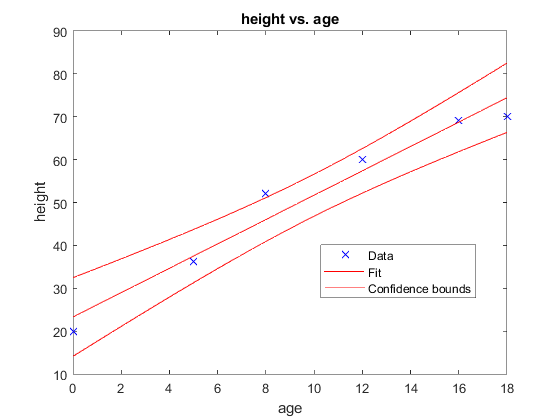

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% The plotting of these fields.
%
% First there is the linear one.

figure;
plot(lm_a)

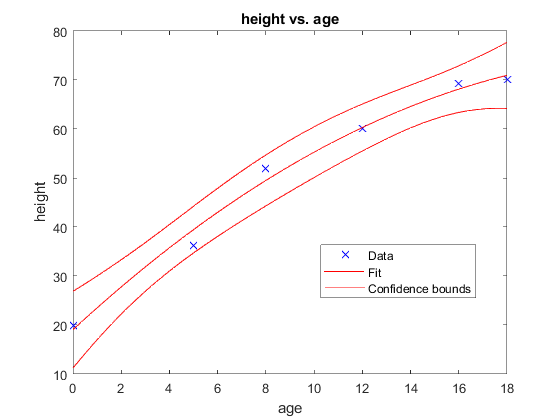


%
% Then the quadradic one...
%

figure;
plot(lm_a2)

## Part 2: Excel Fu!

Now to get scary.  This is new.  [But MATLAB can import and export data from Excel](https://www.mathworks.com/discovery/matlab-excel.html).  This is *only* for the Windows version of MATLAB.  On other operating systems you can export things as a "comma delimited file" (also called a *.CSV" file)

Specifically there are two functions you can review.

    [xlsread](https://www.mathworks.com/help/matlab/ref/xlsread.html?s_tid=srchtitle) to read excel data

    [xlwrite](https://www.mathworks.com/help/matlab/ref/xlswrite.html?searchHighlight=xlswrite&s_tid=doc_srchtitle) will write to an excel file

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% OK now we're going to go off road.  You can also create an excel spradsheet.

%  JGFI xlsread and xlswrite!

%  It's a little scary but it's navigable if you keep your head!

% Let's eat an elephant.  One byte at a time.

%  start with the file name.  

filename = './Excel_Age_Height_Regression_Sandbox_With_Matlab.xlsx';  %you can use a full path here

%   Now the first scary part.  You may see orange in text output.  

xlswrite(filename,             ... % our file name
         {'Age', 'Height'},    ... % this is our header row (use squigly brakcets!)
         'My_Height_Age_Data', ... % this is the sheet where well stick it
         'A1');                    % and this row/col area is where we start to stick it!
%
%   Let's take a look at that file again before we move on. 
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



if all went well you have this spreadsheet in your working directory.

It's just the header line and that's fine (since that's what we asked for...)

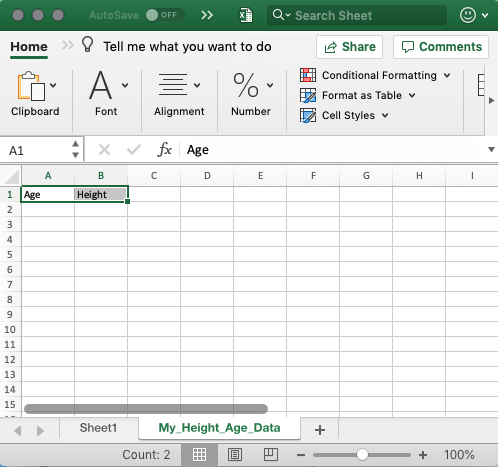

Now it's braver...



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% OK now that you're getting braver... 

xlswrite(filename,             ... % our file name
         age,                  ... % now we drop our data in (aranged facing "down"
         'My_Height_Age_Data', ... % this is the sheet where well stick it
         'A2');                    % and this row/col area is where we stick it!
    
xlswrite(filename,             ... % our file name
         height,                  ... % now we drop our data in (aranged facing "down"
         'My_Height_Age_Data', ... % this is the sheet where well stick it
         'B2');                    % and this row/col area is where we stick it!
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  

And here is our data in the sheet, all sharable for people who don't use MATLAB!

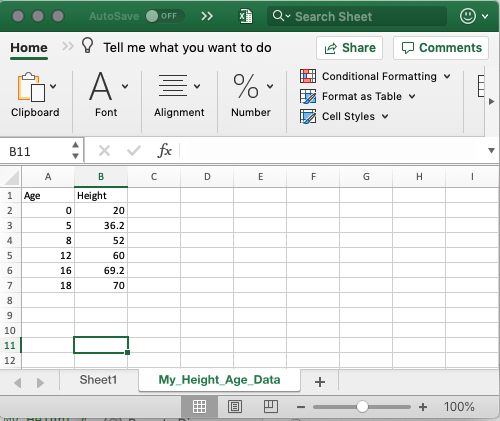

And now to read it!

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         
% OK now that you're moving from brave to just getting cocky... 
%
% now do you think you can read it?

input_age    = xlsread(filename,             ... % our file name
                       'My_Height_Age_Data',  ... % this is the sheet where well grab it
                       'A2:A7');                  % and this is the FULL range from which we pull it
               
input_height = xlsread(filename,              ... % our file name
                       'My_Height_Age_Data',  ... % this is the sheet where well grab it
                       'B2:B7');                  % and this is the FULL range from which we pull it
     
                       
disp(input_age) 

     0
     5
     8
    12
    16
    18



disp(input_height)

   20.0000
   36.2000
   52.0000
   60.0000
   69.2000
   70.0000




% and if you can do this, you ain't gonna be afraid of nothin' !!!!
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

... and that's a good thing becasue we're about to do our roots.

## Part 3: RootFu!

Let's now look at roots... there are multiple ways to attack this problem.

We can start with one of our poster child equatiuons.  


$$f\left(x\right)=x^3 -3x^2 +2\ldotp 3x-0\ldotp 5$$


where


$$x=\left\lbrack \begin{array}{c}
0\ldotp 39\\
0\ldotp 656\\
1\ldotp 954
\end{array}\right\rbrack$$


There are couple functions...

[fzero()](https://www.mathworks.com/help/matlab/ref/fzero.html?searchHighlight=fzero&s_tid=doc_srchtitle) for getting a bracketed solution for roots.. 

For polynomial there is a bass-ackard variant of the polyroots function in Mathcad called [roots()](https://www.mathworks.com/help/matlab/ref/roots.html?searchHighlight=roots&s_tid=doc_srchtitle)

[solve()](https://www.mathworks.com/help/symbolic/solve.html) may be seen as an analog to the symbolic arrow [possibly with a little help the variable precision arithmatic[ vpa()](https://www.mathworks.com/help/symbolic/vpa.html?searchHighlight=vpa&s_tid=doc_srchtitle)]

Also below when plotting our function, I am sliding in a reference line function "[refline()](https://www.mathworks.com/help/stats/refline.html)"

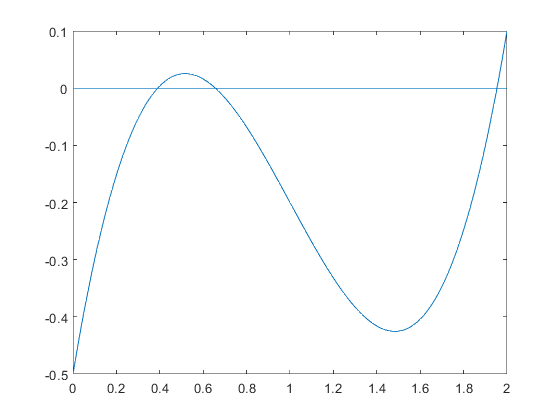

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% OK now let's go back to our section on Roots!


%  remember this fellow?
%     y(x) = x^3 - 3 * x^2 + 2.3 * x - 0.5 = 0
%       x  = 0.39 & 0.656 & 1.954

% We can do this also in Matlab.  There are a vast number of ways to do this
%  but I am only going to demonstrate one general approach

% Let's start by declaring our function.  We do this with a function statement:

% here x is our mystery value so we will mark it with the @(x)
%   the rest of the equation is then written out.

yy_of_x = @(x)  x .^ 3 - 3 * x .^2 + 2.3 * x - 0.5 ;

% let's look at the function:

x_for_plotting = 0: 0.01 : 2;  % make an x array from 0 to 2 by 0.01

% and plot it up!

figure;
plot(x_for_plotting,yy_of_x(x_for_plotting));
    ref_line_slope     = 0;
    ref_line_intercept = 0;
    
    refline(ref_line_slope,  ...
        ref_line_intercept); % this gives us a no-frills zero line with a slop

   


% to get a single root you can use the function "fzero"

x = fzero( yy_of_x, ...  % your function
           [0.5,1.5] )  % your first guess (which can be a single value or

x = 0.6563

                        %    a pair of brackets!

% but this is also a polynomial so you can do some more and it is 
%   reminiscent of Mathcad.

roots([1 -3 2.3 -0.5]) %highest order to lowest order (opposite of Mathcad)

ans =     1.9538
    0.6563
    0.3900



%
% here is a third way... 
% sym x will identify a symbolic equation dependant on x

syms x
f_of_x = x^3 - 3*x^2 + 2.3*x - 0.5 == 0;
x_quadradic_root = solve(f_of_x, x)

$$x\_quadradic\_root = \left(\begin{array}{c} \mathrm{root}\left(z^{3}-3\,z^{2}+\frac{23\,z}{10}-\frac{1}{2},z,1\right)\\ \mathrm{root}\left(z^{3}-3\,z^{2}+\frac{23\,z}{10}-\frac{1}{2},z,2\right)\\ \mathrm{root}\left(z^{3}-3\,z^{2}+\frac{23\,z}{10}-\frac{1}{2},z,3\right) \end{array}\right)$$


% In this case, it's returning a mid-way step. and it's 
%    not very intuitve.  If this happens you can use this last
%    step using the "variable-precision-arithmatic" (vpa)

vpa(x_quadradic_root)

$$ans = \left(\begin{array}{c} 0.38995436898991359967676545300809\\ 0.65626766441633767590482744679622\\ 1.9537779665937487244184071001957 \end{array}\right)$$


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Part 4: Linear-Eq-Fu!

Now we can get to what MATLAB is meant to do... Linear Algebra.  Remember's it's shot for Matrix Laboratory.  

We've done some of this in lass together but let's play with these functions...


$$\begin{array}{l}
f\left(x,y\right)=2x-y+2\\
g\left(x,y\right)=2x+y-6
\end{array}$$



$$\mathbf{A}\vec{x} -\vec{b} =0$$



$$\left\lbrack \begin{array}{c}
2 & -1\\
2 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-2\\
6
\end{array}\right\rbrack =0$$


There are multiple ways to do this too... 

You can use traditional matrix algebra, or use some functions that come with MATLAB such as

[linsolve()](https://www.mathworks.com/help/matlab/ref/linsolve.html?searchHighlight=linsolve()&s_tid=doc_srchtitle), which is does it under the guise of a function

and also using our [solve()](https://www.mathworks.com/help/symbolic/solve.html) function from above...

[equationsToMatrix()](https://www.mathworks.com/help/symbolic/equationstomatrix.html?searchHighlight=equationsToMatrix&s_tid=doc_srchtitle) let's us take a linear system of equations and re-write them as matrix-based systems.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%

% as with a single non-linear equation you can also solve a system of
% equations

%    f(x,y) = 2x - y + 2 = 0
%    g(x,y) = 2x + y - 6 = 0
%    [x,y] = [1,2]

% you undestand at this point Matrix-Fu!

A = [2 -1 ; ...  %  Break the rows with a ";"
     2  1 ]

A =      2    -1
     2     1


 
b = [ 2 ; ...
     -6 ]

b =      2
    -6


 
xx1 = -( inv(A) * b ) % old habits have me using this version

xx1 =      1
     4


%
% Matlab may nag at you here. For small matricies this isn't a big
%   issue but for HUGE matricies (not like your truss assignment) this
%   may increase the time for your script to run.  From a teaching
%   perspective I prefer the above inefficient way for better
%   "transparency" from the math perspectiec. 

xx2 = -( A^-1   * b ) %  this one works, too.

xx2 =      1
     4


xx3 = linsolve(A,-b)  % and there is this one as well.

xx3 =      1
     4



% Remember that we are also able to use "root" type
%  attack methods since these are root problems
%   (just using multiple equations!)
%
% in this case we can also "pre-declare" theses functions
% before inserting them in the root equation with the sims notifier

syms x y % this creates symbolic objects dependant on x and y
f_of_x = 2 * x - y + 2 == 0 % here is your f(x,y)

$$f\_of\_x = 2\,x-y+2=0$$

g_of_x = 2 * x + y - 6 == 0 % here is your g(x,y)

$$g\_of\_x = 2\,x+y-6=0$$


my_x_and_y = solve([f_of_x, g_of_x], [x, y]) % this will create two answers

my_x_and_y = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


my_x = my_x_and_y.x                          % hidden like your RMSE

$$my\_x = 1$$

my_y = my_x_and_y.y                          % and other fields were in

$$my\_y = 4$$

                                             % in the regression section

% want to play with both this form of solution AND matricies?
%   Let's turn the above into our A and b matrixes.

[AA, bb] = equationsToMatrix([f_of_x, g_of_x], [x, y])

$$AA = \left(\begin{array}{cc} 2 & -1\\ 2 & 1 \end{array}\right)$$

$$bb = \left(\begin{array}{c} -2\\ 6 \end{array}\right)$$


my_new_x_and_y =  inv(AA) * bb % no minus needed.

$$my\_new\_x\_and\_y = \left(\begin{array}{c} 1\\ 4 \end{array}\right)$$


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
